clear
%This is the FINAL VERSION of the Predictive Numerical Model for the Yanmar L100N Compression-Ignition Engine
%----------------------------------------------------------------------------------------------------------------------------------------------------------------

**User Inputs**

%Yanmar Diesel Engine Geometric Parameters
l=118e-3;%connecting rod length in m
L=75e-3;%stroke length in m
a=L/2;%crank radius in m
B=86e-3; %Bore in m
Vd=(L*pi*B^2)/4; %displacement volume in m3
R=l/a;
r=17.5;%18;%compression ratio (according to Heywood, r is 14 to 22 for CI Engines)
Vc=Vd/(r-1); %minimum in-cylinder volume at TDC

%Ambient Conditions
P_atm =1014*100; %Atmospheric air pressure (Pa)
Pamb=0.9*P_atm; %ambient pressure [Pa] - ambient pressure at intake valves assumed below atmospheric pressure, due to pressure losses in manifold
Tamb=25+273.15;%ambient conditions [K]

%Cylinder Charge Parameters
nf=0.99; %combustion efficiency for diesel engines (ref: Heywood txtbook)
Tw=485; %wall temp in K(Goering, 1998) 485
Rg = 287; %Ideal gas constant (J/kg*K)
gamma_air=1.4; %specific heat ratio for air
gamma_CP=1.33; %specific heat ratio of hot products of combustion  (cengel, et al. 2019)

% Exhaust/Intake strokes
Cd=0.6; %Discharge coefficient
Dv_IV=0.48*B; %Intake valve head diameter for a flat, twin valve cylinder head
Dv_EV=0.44*B; %Exhaust valve head diameter for a flat, twin valve cylinder head
Lv_max=4.46e-3; %maximum valve lift m2

%Valve timing for one cycle
IVO=-5; %intake valve opening
IVC=225; %intake valve closing
EVO=500; %exhaust valve opening
EVC=730; %exhaust valve closing

N=3000; %Speed rpm
T=20; %Load Nm
BP=0;%Bioblend Percentage [for B20, BP=0.2]
[Q_LHV,~]=BioBlend(BP); %LHV of biodiesel blend in J/kg

%Reference conditions for Woschni Heat Transfer at IVC
Pr=1014*100; %Pa
Tr=25+273.15;%K
Vr=V(Vc,r,R,IVC,B,L);

**Regression Equations of Double Wiebe Function Parameters and Fuel Mass  **

%Load the example correlation coefficient data for the combustion correlation equations, which is generated using the script called...
% "Wiebe_correlation_final". The data is saved in the folder: Example_Data\correlation coefficients.  The user must use their own data

 load('Example_Data\correlation coefficients\B_S_SOC_p.mat');
 load('Example_Data\correlation coefficients\B_D_SOC_p.mat');
 load('Example_Data\correlation coefficients\B_D_SOC_d.mat');
 load('Example_Data\correlation coefficients\B_S_DOC_p.mat');
 load('Example_Data\correlation coefficients\B_D_DOC_p.mat');
 load('Example_Data\correlation coefficients\B_D_DOC_d.mat');
 load('Example_Data\correlation coefficients\B_S_m_p.mat');
 load('Example_Data\correlation coefficients\B_D_m_p.mat');
 load('Example_Data\correlation coefficients\B_D_m_d.mat');
 load('Example_Data\correlation coefficients\B_S_b_p.mat');
 load('Example_Data\correlation coefficients\B_D_b_p.mat');
 load('Example_Data\correlation coefficients\B_D_b_d.mat');
 load('Example_Data\correlation coefficients\B_Mf.mat');


 D_SOC_p_relation = @ (N,T,BP) B_D_SOC_p(1)+B_D_SOC_p(2).*N+B_D_SOC_p(3).*T+B_D_SOC_p(4).*BP+B_D_SOC_p(5).*N.^2+B_D_SOC_p(6).*T.^2+B_D_SOC_p(7).*BP.^2+B_D_SOC_p(8).*N.*T+B_D_SOC_p(9).*N.*BP+B_D_SOC_p(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_SOC_d_relation = @ (N,T,BP) B_D_SOC_d(1)+B_D_SOC_d(2).*N+B_D_SOC_d(3).*T+B_D_SOC_d(4).*BP+B_D_SOC_d(5).*N.^2+B_D_SOC_d(6).*T.^2+B_D_SOC_d(7).*BP.^2+B_D_SOC_d(8).*N.*T+B_D_SOC_d(9).*N.*BP+B_D_SOC_d(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20] 
 D_DOC_p_relation = @ (N,T,BP) B_D_DOC_p(1)+B_D_DOC_p(2).*N+B_D_DOC_p(3).*T+B_D_DOC_p(4).*BP+B_D_DOC_p(5).*N.^2+B_D_DOC_p(6).*T.^2+B_D_DOC_p(7).*BP.^2+B_D_DOC_p(8).*N.*T+B_D_DOC_p(9).*N.*BP+B_D_DOC_p(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_DOC_d_relation = @ (N,T,BP) B_D_DOC_d(1)+B_D_DOC_d(2).*N+B_D_DOC_d(3).*T+B_D_DOC_d(4).*BP+B_D_DOC_d(5).*N.^2+B_D_DOC_d(6).*T.^2+B_D_DOC_d(7).*BP.^2+B_D_DOC_d(8).*N.*T+B_D_DOC_d(9).*N.*BP+B_D_DOC_d(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_m_p_relation = @ (N,T,BP) B_D_m_p(1)+B_D_m_p(2).*N+B_D_m_p(3).*T+B_D_m_p(4).*BP+B_D_m_p(5).*N.^2+B_D_m_p(6).*T.^2+B_D_m_p(7).*BP.^2+B_D_m_p(8).*N.*T+B_D_m_p(9).*N.*BP+B_D_m_p(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_m_d_relation = @ (N,T,BP) B_D_m_d(1)+B_D_m_d(2).*N+B_D_m_d(3).*T+B_D_m_d(4).*BP+B_D_m_d(5).*N.^2+B_D_m_d(6).*T.^2+B_D_m_d(7).*BP.^2+B_D_m_d(8).*N.*T+B_D_m_d(9).*N.*BP+B_D_m_d(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_b_p_relation = @ (N,T,BP) B_D_b_p(1)+B_D_b_p(2).*N+B_D_b_p(3).*T+B_D_b_p(4).*BP+B_D_b_p(5).*N.^2+B_D_b_p(6).*T.^2+B_D_b_p(7).*BP.^2+B_D_b_p(8).*N.*T+B_D_b_p(9).*N.*BP+B_D_b_p(10).*BP.*T+B_D_b_p(11).*N.*T.*BP; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 D_b_d_relation = @ (N,T,BP) B_D_b_d(1)+B_D_b_d(2).*N+B_D_b_d(3).*T+B_D_b_d(4).*BP+B_D_b_d(5).*N.^2+B_D_b_d(6).*T.^2+B_D_b_d(7).*BP.^2+B_D_b_d(8).*N.*T+B_D_b_d(9).*N.*BP+B_D_b_d(10).*BP.*T+B_D_b_d(11).*N.*T.*BP; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 Mf_relation = @ (N,T,BP) B_Mf(1)+B_Mf(2).*N+B_Mf(3).*T+B_Mf(4).*BP;%feul mass in kg %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20] 

%Wiebe Parameters and Fuel Mass
D_SOC_p=D_SOC_p_relation(N,T,BP*100);
D_SOC_d=D_SOC_d_relation(N,T,BP*100);
D_DOC_p=D_DOC_p_relation(N,T,BP*100);
D_DOC_d=D_DOC_d_relation(N,T,BP*100);
D_m_p=D_m_p_relation(N,T,BP*100);
D_m_d=D_m_d_relation(N,T,BP*100);
D_b_p=D_b_p_relation(N,T,BP*100);
D_b_d=D_b_d_relation(N,T,BP*100);
mf=Mf_relation(N,T,BP*100);

**Regression Equations of Single Wiebe Function Parameters **

 S_SOC_p_relation = @ (N,T,BP) B_S_SOC_p(1)+B_S_SOC_p(2).*N+B_S_SOC_p(3).*T+B_S_SOC_p(4).*BP+B_S_SOC_p(5).*N.^2+B_S_SOC_p(6).*T.^2+B_S_SOC_p(7).*BP.^2+B_S_SOC_p(8).*N.*T+B_S_SOC_p(9).*N.*BP+B_S_SOC_p(10).*BP.*T+B_S_SOC_p(11).*N.*T.*BP; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 S_DOC_p_relation = @ (N,T,BP) B_S_DOC_p(1)+B_S_DOC_p(2).*N+B_S_DOC_p(3).*T+B_S_DOC_p(4).*BP+B_S_DOC_p(5).*N.^2+B_S_DOC_p(6).*T.^2+B_S_DOC_p(7).*BP.^2+B_S_DOC_p(8).*N.*T+B_S_DOC_p(9).*N.*BP+B_S_DOC_p(10).*BP.*T+B_S_DOC_p(11).*N.*T.*BP; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 S_m_p_relation = @ (N,T,BP) B_S_m_p(1)+B_S_m_p(2).*N+B_S_m_p(3).*T+B_S_m_p(4).*BP+B_S_m_p(5).*N.^2+B_S_m_p(6).*T.^2+B_S_m_p(7).*BP.^2+B_S_m_p(8).*N.*T+B_S_m_p(9).*N.*BP+B_S_m_p(10).*BP.*T; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
 S_b_p_relation = @ (N,T,BP) B_S_b_p(1)+B_S_b_p(2).*N+B_S_b_p(3).*T+B_S_b_p(4).*BP+B_S_b_p(5).*N.^2+B_S_b_p(6).*T.^2+B_S_b_p(7).*BP.^2+B_S_b_p(8).*N.*T+B_S_b_p(9).*N.*BP+B_S_b_p(10).*BP.*T+B_S_b_p(11).*N.*T.*BP; %N=Speed [RPM], T=Torque [Nm], BP=Bioblend Percentage [for B20, BP=20]
  
%Wiebe Parameters
S_SOC_p=S_SOC_p_relation(N,T,BP*100);
S_DOC_p=S_DOC_p_relation(N,T,BP*100);
S_m_p=S_m_p_relation(N,T,BP*100);
S_b_p=S_b_p_relation(N,T,BP*100);

**Intake Stroke**

%Initial Conditions
Pcyl_IVO= Pamb;% initial guess of cylinder pressure [Pa] at IVO  
Tcyl_IVO= 610;% initial guess of cylinder temperature [K] at IVO
m_IVO=(Pcyl_IVO*V(Vc,r,R,IVO,B,L))/(Rg*Tcyl_IVO); %cylinder mass at IVO in kg

solver_IV=@(theta,y) [((gammaFluid(y(2))-1)/V(Vc,r,R,theta,B,L))*(-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)+...
    (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)...
    /(gammaFluid(Tamb)-1))+gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720)/...
    (gammaFluid(y(2))-1))-(gammaFluid(y(2))*y(1)*dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
    (dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)+...
    dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720))*...
    (Rg*y(2)-(gammaFluid(y(2))-1)*Rg*y(2)/(gammaFluid(y(2))-1))/V(Vc,r,R,theta,B,L); %Pa/deg

    y(2)*(gammaFluid(y(2))-1)*((-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)/(y(1)*V(Vc,r,R,theta,B,L)))-(dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
    (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)/((gammaFluid(Tamb)-1)*y(1)*V(Vc,r,R,theta,B,L)))+...
    (gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720)/...
    ((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)))-Rg*y(2)*(dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)+...
    dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720))/((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)));%K/deg

     dm_dtheta(theta,Cd,Rg,gamma_air,Pamb,Tamb,y(1),y(2),N,Dv_IV,Dv_EV,Lv_max,IVO,IVC,EVO-720,EVC-720)];%kg/deg

y0_IV=[Pcyl_IVO;Tcyl_IVO;m_IVO];
theta_span_IV=linspace(IVO,IVC,IVC*10-IVO*10+1);
[T_IV,Y_IV]=ode45(solver_IV,theta_span_IV,y0_IV);

**Compression and Expansion Strokes**

%Initial conditions at IVC
P_initial_IVC= Y_IV(IVC*10-IVO*10+1,1);%P_atm; %Pa
T_initial_IVC= Y_IV(IVC*10-IVO*10+1,2);%25+273.15;%K 
V_initial_IVC=V(Vc,r,R,IVC,B,L); %Volume at IVC
       
xD_p_pred=[D_SOC_p,D_DOC_p,D_m_p,D_b_p]; %predicted Double Wiebe premixed combustion parameters
xD_d_pred=[D_SOC_d,D_DOC_d,D_m_d,D_b_d]; %predicted Double Wiebe diffusion combustion parameters

%Solving for pressure and temperature vs crank angle - Fitting Double-Wiebe directly to HRR
solver_Double_Wiebe_HRR= @(theta,x)[(-gammaFluid(x(2))/V(Vc,r,R,theta,B,L))*x(1)*dV_dTheta(Vc,r,R,theta,B,L)+(gammaFluid(x(2))-1)*(HRR_Double_predict(xD_p_pred,xD_d_pred,theta,Q_LHV,nf,mf)-HT_Woschni(B,L,N,T_initial_IVC,P_initial_IVC,V_initial_IVC,x(1),x(2),Vc,r,R,Tw,theta))/V(Vc,r,R,theta,B,L);
    x(2)*(gammaFluid(x(2))-1)*(-dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L)+(HRR_Double_predict(xD_p_pred,xD_d_pred,theta,Q_LHV,nf,mf)-HT_Woschni(B,L,N,T_initial_IVC,P_initial_IVC,V_initial_IVC,x(1),x(2),Vc,r,R,Tw,theta))/(x(1)*V(Vc,r,R,theta,B,L)))]; % first equation of anonymous function ...
% is dP/dtheta and second is dT/dtheta
options = odeset('RelTol', 1e-7, 'AbsTol', 1e-9);

x0=[P_initial_IVC;T_initial_IVC]; %Initial conditions
theta_span_CE=linspace(IVC,EVO,EVO*10-10*IVC+1); %crank angles
[~,X_d_HRR]=ode45(solver_Double_Wiebe_HRR,theta_span_CE, x0,options); %use ode45 to solve for dP/dtheta and dT/dtheta   


**Exhaust Stroke**

%Initial Conditions Exhaust
Pcyl_EVO=X_d_HRR(EVO*10-10*IVC+1,1);%Pa
Tcyl_EVO=X_d_HRR(EVO*10-10*IVC+1,2);%K
m_EVO=(Pcyl_EVO*V(Vc,r,R,EVO,B,L))/(Rg*Tcyl_EVO); %cylinder mass at EVO in kg        
        
solver_EV=@(theta,y) [((gammaFluid(y(2))-1)/V(Vc,r,R,theta,B,L))*(-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)+...
    (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO+720,IVC+720)...
    /(gammaFluid(Tamb)-1))+gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO,EVC)/...
    (gammaFluid(y(2))-1))-(gammaFluid(y(2))*y(1)*dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
    (dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO+720,IVC+720)+...
    dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO,EVC))*...
    (Rg*y(2)-(gammaFluid(y(2))-1)*Rg*y(2)/(gammaFluid(y(2))-1))/V(Vc,r,R,theta,B,L); %Pa/deg

    y(2)*(gammaFluid(y(2))-1)*((-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)/(y(1)*V(Vc,r,R,theta,B,L)))-(dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
    (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO+720,IVC+720)/((gammaFluid(Tamb)-1)*y(1)*V(Vc,r,R,theta,B,L)))+...
    (gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO,EVC)/...
    ((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)))-Rg*y(2)*(dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO+720,IVC+720)+...
    dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO,EVC))/((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)));%K/deg

     dm_dtheta(theta,Cd,Rg,gamma_air,Pamb,Tamb,y(1),y(2),N,Dv_IV,Dv_EV,Lv_max,IVO+720,IVC+720,EVO,EVC)];%kg/deg
        
y0_EV=[Pcyl_EVO;Tcyl_EVO;m_EVO];
theta_span_EV=linspace(EVO,EVC,EVC*10-EVO*10+1);
[T_EV_D,Y_EV_D]=ode45(solver_EV,theta_span_EV,y0_EV);


**ITERATIVE STEP  ITERATIVE STEP   ITERATIVE STEP      ITERATIVE STEP    ITERATIVE STEP      ITERATIVE STEP    ITERATIVE STEP      ITERATIVE STEP       **

T_IVO_EX=Y_EV_D((720+IVO)*10-EVO*10+1,2); %Predicted Temperature at IVO+720 CAD
P_IVO_EX=Y_EV_D((720+IVO)*10-EVO*10+1,1); %Predicted Pressure at IVO+720 CAD
iteration_counter=1;
omega=0.3; %Relaxation factor
max_iterations=1000; %maximum iterations

while ((abs(T_IVO_EX-Tcyl_IVO)>1)||(abs(P_IVO_EX-Pcyl_IVO)>1))&&(iteration_counter<max_iterations)
        
        

**       Intake Stroke**

        % Update with relaxation instead of direct replacement
        Tcyl_IVO = (1-omega)*Tcyl_IVO + omega*T_IVO_EX;
        Pcyl_IVO = (1-omega)*Pcyl_IVO + omega*P_IVO_EX;
   
        m_IVO=(Pcyl_IVO*V(Vc,r,R,IVO,B,L))/(Rg*Tcyl_IVO); %cylinder mass at IVO in kg
        
        solver_IV=@(theta,y) [((gammaFluid(y(2))-1)/V(Vc,r,R,theta,B,L))*(-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)+...
            (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)...
            /(gammaFluid(Tamb)-1))+gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720)/...
            (gammaFluid(y(2))-1))-(gammaFluid(y(2))*y(1)*dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
            (dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)+...
            dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720))*...
            (Rg*y(2)-(gammaFluid(y(2))-1)*Rg*y(2)/(gammaFluid(y(2))-1))/V(Vc,r,R,theta,B,L); %Pa/deg
        
            y(2)*(gammaFluid(y(2))-1)*((-HT_Woschni(B,L,N,Tr,Pr,Vr,y(1),y(2),Vc,r,R,Tw,theta)/(y(1)*V(Vc,r,R,theta,B,L)))-(dV_dTheta(Vc,r,R,theta,B,L)/V(Vc,r,R,theta,B,L))+...
            (gammaFluid(Tamb)*Rg*Tamb*dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)/((gammaFluid(Tamb)-1)*y(1)*V(Vc,r,R,theta,B,L)))+...
            (gammaFluid(y(2))*Rg*y(2)*dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720)/...
            ((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)))-Rg*y(2)*(dm_dtheta_intake(theta,Cd,Rg,gammaFluid(Tamb),Pamb,Tamb,y(1),y(2),N,Dv_IV,Lv_max,IVO,IVC)+...
            dm_dtheta_exhaust(theta,Cd,Rg,gammaFluid(y(2)),Pamb,Tamb,y(1),y(2),N,Dv_EV,Lv_max,EVO-720,EVC-720))/((gammaFluid(y(2))-1)*y(1)*V(Vc,r,R,theta,B,L)));%K/deg
        
             dm_dtheta(theta,Cd,Rg,gamma_air,Pamb,Tamb,y(1),y(2),N,Dv_IV,Dv_EV,Lv_max,IVO,IVC,EVO-720,EVC-720)];%kg/deg
        
        y0_IV=[Pcyl_IVO;Tcyl_IVO;m_IVO];
        theta_span_IV=linspace(IVO,IVC,IVC*10-IVO*10+1);
        [T_IV,Y_IV]=ode45(solver_IV,theta_span_IV,y0_IV);     

**        Compression and Expansion Strokes**

        %Initial conditions at IVC
        P_initial_IVC= Y_IV(IVC*10-IVO*10+1,1); %Pa
        T_initial_IVC= Y_IV(IVC*10-IVO*10+1,2);%K 
        V_initial_IVC=V(Vc,r,R,IVC,B,L); %Volume at IVC
                    
        x0=[P_initial_IVC;T_initial_IVC]; %Initial conditions
        [~,X_d_HRR]=ode45(solver_Double_Wiebe_HRR,theta_span_CE, x0, options); %use ode45 to solve for dP/dtheta and dT/dtheta   

**       Exhaust Stroke**

        %Initial Conditions Exhaust
        Pcyl_EVO=X_d_HRR(EVO*10-10*IVC+1,1);%Pa
        Tcyl_EVO=X_d_HRR(EVO*10-10*IVC+1,2);%K
        m_EVO=(Pcyl_EVO*V(Vc,r,R,EVO,B,L))/(Rg*Tcyl_EVO); %cylinder mass at EVO in kg
        
        y0_EV=[Pcyl_EVO;Tcyl_EVO;m_EVO];                       
        [T_EV_D,Y_EV_D]=ode45(solver_EV,theta_span_EV,y0_EV);



        **Calculate New Values**

        
        T_IVO_EX=Y_EV_D((720+IVO)*10-EVO*10+1,2); %Predicted Temperature at IVO+720 CAD
        P_IVO_EX=Y_EV_D((720+IVO)*10-EVO*10+1,1); %Predicted Pressure at IVO+720 CAD
        iteration_counter=iteration_counter+1;


        % fprintf('iteration counter: %d\n', iteration_counter);
        % fprintf('T_IVO_EX: %d\n', T_IVO_EX);
        % fprintf('Tcyl_IVO: %d\n', Tcyl_IVO);
        % fprintf('P_IVO_EX: %d\n', P_IVO_EX);
        % fprintf('Pcyl_IVO: %d\n', Pcyl_IVO);
end

**Check for convergence**

if iteration_counter >= max_iterations
    warning('Convergence failed after %d iterations', max_iterations);
    fprintf('Final errors: T_error = %.2f K, P_error = %.2f Pa\n', ...
            abs(T_IVO_EX-Tcyl_IVO), abs(P_IVO_EX-Pcyl_IVO));
else
    fprintf('Converged successfully after %d iterations\n', iteration_counter);
end

Converged successfully after 27 iterations


**Simulation Results**

Pressure_intake=Y_IV(1:IVC*10-IVO*10,1); %Intake Pressure || %dont include the last point because it will be repeated in compression/expansion solution
Temp_intake=Y_IV(1:IVC*10-IVO*10,2); %Intake Temperature || %dont include the last point because it will be repeated in compression/expansion solution

Pressure_CE=X_d_HRR(1:EVO*10-IVC*10,1); %Compression+Expansion Pressure|| %dont include the last point because it will be repeated in exhaust solution 
Temp_CE=X_d_HRR(1:EVO*10-IVC*10,2); %Compression+Expansion Temperature|| %dont include the last point because it will be repeated in exhaust solution

Pressure_exhaust=Y_EV_D(:,1);  % Exhaust Pressure 
Temp_exhaust=Y_EV_D(:,2);  % Exhaust Temperature 
        
        
%Pressure and Temperature for Entire Cycle 
Pressure_Cycle=[Pressure_intake',Pressure_CE',Pressure_exhaust'];
Temp_Cycle=[Temp_intake',Temp_CE',Temp_exhaust'];

**Isentropic Calculation**

% Compare with direct isentropic calculation
V_solved=V(Vc,r,R,linspace(IVC,EVO,EVO*10-10*IVC+1),B,L);
P_direct = P_initial_IVC * (V_initial_IVC./V_solved).^gammaFluid((Tcyl_EVO-T_initial_IVC)/2); %constant specific heat at average temp
T_direct = T_initial_IVC * (V_initial_IVC./V_solved).^(gammaFluid((Tcyl_EVO-T_initial_IVC)/2)-1); %constant specific heat at average temp

**Heat Release Rate**       

theta_span_HRR=linspace(350,450,2000); %Approximate Combustion Crank Angle Duration
Heat_Release_Rate=HRR_Double_predict(xD_p_pred,xD_d_pred,theta_span_HRR,Q_LHV,nf,mf); %Heat Release Rate using Double Wiebe Function


**Performance Parameters**

Volume_CE=V(Vc,r,R,theta_span_CE,B,L); %[m^3] Volume corresponding to crank angle during compression and expansion
W_g=trapz(Volume_CE',X_d_HRR(:,1)); %[J]  gross indicated work = integration of pressure during expansion and compression with volume
GIMEP=W_g./Vd; %Gross Indicated Mean Effective Pressure [Pa]
FRMEP=FMEP(N,L)*1000; %Friction Mean Effective Pressure [Pa]
BMEP=GIMEP-FRMEP; %Brake Mean Effective Pressure [Pa]
nR=2; %number of revolutions per cycle
Pb=BMEP.*Vd.*N./(nR.*60); %Brake Power [J/s];
T=Pb./(N.*2.*pi./60); %Torque (Nm)

charges_per_sec = (N./60)./2;
Mfdot=mf.*charges_per_sec; %mass flow rate in kg/s
sfc=(1e6.*60.*60).*Mfdot/Pb; %specific fuel consumption in g/(kW*h)


**Plot Graphs**

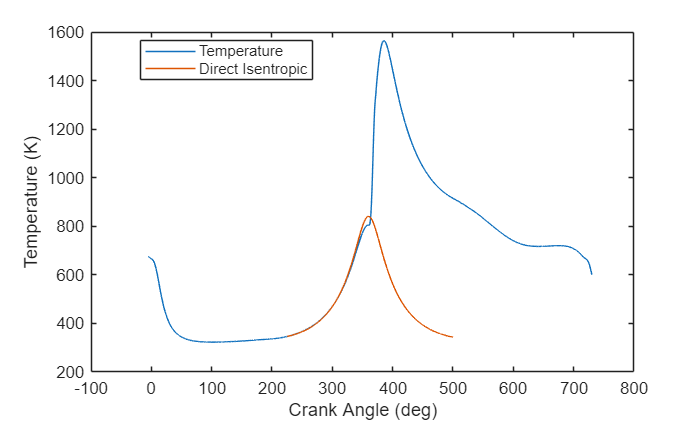

plot(linspace(IVO,EVC,EVC*10-IVO*10+1),Temp_Cycle);
hold on;
plot(linspace(IVC,EVO,EVO*10-10*IVC+1),T_direct)
legend('Temperature','Direct Isentropic', 'Location', 'best'); hold off;
xlabel('Crank Angle (deg)'); ylabel('Temperature (K)');

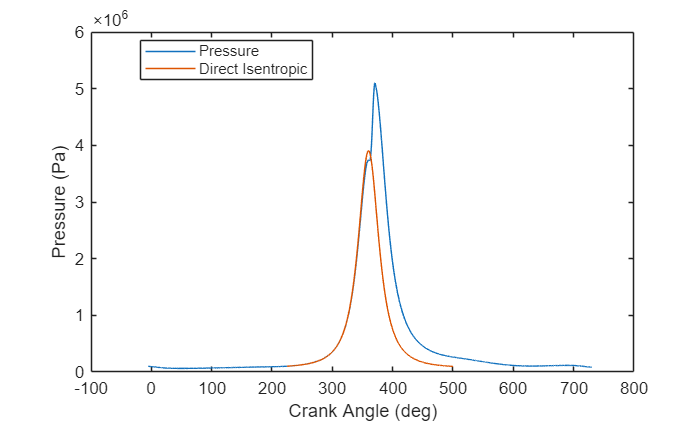



plot(linspace(IVO,EVC,EVC*10-IVO*10+1),Pressure_Cycle);
hold on;
plot(linspace(IVC,EVO,EVO*10-10*IVC+1),P_direct)
legend('Pressure','Direct Isentropic', 'Location', 'best'); hold off;
xlabel('Crank Angle (deg)'); ylabel('Pressure (Pa)');

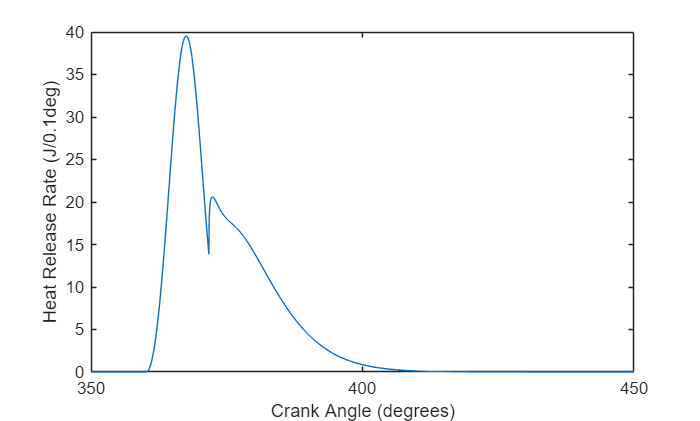

plot(theta_span_HRR, Heat_Release_Rate);
xlabel('Crank Angle (degrees)')
ylabel("Heat Release Rate (J/0.1deg)")

 
%-------------------------------------------------------------------------------------------------------------------------------
function V=V(Vc,r,R,theta,B,L) %Volume vs crank angle 
    [V,~,~]=V_dV(Vc,r,R,theta,B,L);
end

function dV_dtheta=dV_dTheta(Vc,r,R,theta,B,L) % dV/dtheta TDC=0deg and BDC=180deg
    [~,dV_dtheta,~]=V_dV(Vc,r,R,theta,B,L);
end 

function Q_w=HT_Woschni(B,L,N,Tr,Pr,Vr,P,T,Vc,r,R,Tw,theta)
    [Q_w,~]=Heat_Transfer_Woschni(B,L,N,Tr,Pr,Vr,P,T,Vc,r,R,Tw,theta);
end
